# Rozwiązywania układu równań liniowych z wykorzystaniem Symbolic Math Toolbox. 

**Celem ćwiczenia: **jest obliczenie układu równań liniowych i reprezentacja graficzna rozwiązania. 

Wykorzystany zostanie  Symbolic Math Toolbox, który wykorzystywany jest gdy potrzebne są dokładne, analityczne rozwiązania matematyczne. 

W tym ćwiczeniu ukłąd równań zostanie zdefiniownay w postaci symbolicznej. 

Do rozwiazania układu równań wykorzystana zostanie funkcja `solve z `Symbolic Math Toolbox.

Wyniki zostaną przedstawione za pomocą wizualizacji 3D w wybranym zakresie wartości układu kartezjańskiego (x,y,z).

Wyznaczony zostanie również punkt przecięcia trzech płaszczyzn. 

Zadanie:

Skrypt ten pozwala na wizualizację i interpretację rozwiązania układu równań liniowych w przestrzeni trójwymiarowej.


$$-x+3z=1; 

y+z=-1;

y-2z=2$$


%% Graficzne rozwiązanie układu równań liniowych
% Równania:
% -x + 3z = 1
% y + z = -1
% y - 2z = 2

% Definiowanie symbolicznych zmiennych
syms x y z

Funkcja `syms` służy do definiowania zmiennych symbolicznych, które można używać w równaniach, całkach, pochodnych itp.

Po utworzeniu zmiennych symbolicznych `x`,y,z można traktować jak zmienne algebraiczne, a nie wartości liczbowe.

% Definiowanie układu równań
eq1 = -x + 3*z == 1;
eq2 = y + z == -1;
eq3 = y - 2*z == 2;

% Rozwiązanie układu równań symbolicznie
sol = solve([eq1, eq2, eq3], [x, y, z])

sol = struct with fields:
    x: -4
    y: 0
    z: -1


Funkcja `solve` w MATLAB służy do symbolicznego rozwiązywania równań i układów równań. 

Jest szczególnie przydatna, gdy należy znaleźć dokładne, analityczne rozwiązania dla równań algebraicznych. 

Funkcja `solve` może być używana zarówno do równań jednej zmiennej, jak i do układów równań wielu zmiennych.

Warto też wspomnieć, że `solve` automatycznie dobiera zmienne do rozwiązania, jeśli nie są podane. Ponieważ podano wszystkie zmienne (`[x, y, z]`), funkcja `solve` znajduje dokładne wartości tych zmiennych.

% Wyświetlenie rozwiązania
disp('Rozwiązanie układu równań:');

Rozwiązanie układu równań:


disp(['x = ' char(sol.x)]);

x = -4


disp(['y = ' char(sol.y)]);

y = 0


disp(['z = ' char(sol.z)]);

z = -1



% Konwersja na liczby dla wykresu
x_sol = double(sol.x);
y_sol = double(sol.y);
z_sol = double(sol.z);

Warto zwócić uwagę, że przy definiowaniu siatki dla płaszczyzn korzystamy tylko ze zmiennych `x` i `z`, podczas gdy `y` jest wyznaczane z równań. 

Jest to zgodne z tym, że zmienne `x` i `z` tworzą siatkę dla płaszczyzn, a `y` jest obliczane.

%% Tworzenie siatki dla zmiennych x i z
[x_vals, z_vals] = meshgrid(-5:0.5:5, -5:0.5:5);

% Wyrażenia z równaniami w postaci rozwiązanej dla zmiennych y
% -x + 3*z = 1;
% y + z = -1;
% y - 2*z = 2;

y1_vals = (-x_vals + 3 * z_vals + 1); % z eq1
y2_vals = -z_vals - 1;                % z eq2
y3_vals = (2 + 2 * z_vals);           % z eq3

`y1_vals`, `y2_vals`, `y3_vals - `są to równania płaszczyzn przekształcone do wyrażenia `y = f(x, z)`.

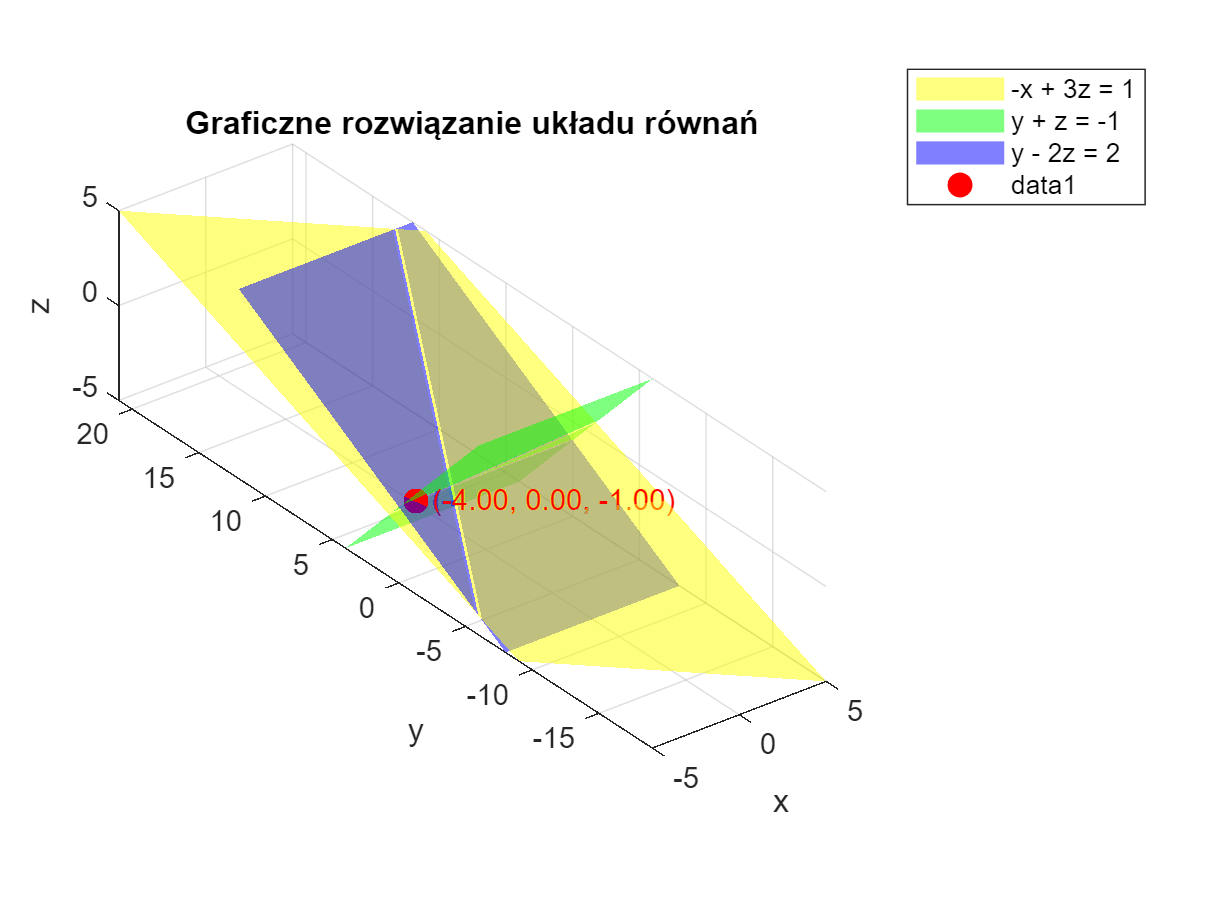

% Wykres trójwymiarowy płaszczyzn
figure;
surf(x_vals, y1_vals, z_vals, 'FaceAlpha', 0.5, 'EdgeColor', 'none','FaceColor','yellow');
hold on;
surf(x_vals, y2_vals, z_vals, 'FaceAlpha', 0.5, 'EdgeColor', 'none','FaceColor','green');
surf(x_vals, y3_vals, z_vals, 'FaceAlpha', 0.5, 'EdgeColor', 'none','FaceColor','blue');

% Ustawienia osi
xlabel('x');
ylabel('y');
zlabel('z');
title('Graficzne rozwiązanie układu równań');
legend('-x + 3z = 1', 'y + z = -1', 'y - 2z = 2');

% Zaznaczenie punktu przecięcia
plot3(x_sol, y_sol, z_sol, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
text(x_sol, y_sol, z_sol, sprintf('  (%.2f, %.2f, %.2f)', x_sol, y_sol, z_sol), 'Color', 'red');

% Dostosowanie widoku
axis equal;
grid on;
view(3);
hold off;

Symboliczne zmienne umożliwiają rozwiązywanie równań i nierówności bez przybliżeń.

Symbolic Math Toolbox pozwala na obliczanie pochodnych i całek w sposób analityczny a także pozwala na obliczanie transformat Laplace’a i Fouriera.

**Przykłady zastosowania**

- **Analiza wyrażeń matematycznych**: Symboliczne podejście jest przydatne, gdy chcemy przeanalizować dokładne właściwości funkcji lub równań, np. obliczenie miejsc zerowych wielomianu lub wyznaczenie asymptot funkcji.

- **Równania różniczkowe**: Symboliczne zmienne umożliwiają analityczne rozwiązywanie równań różniczkowych, co jest istotne w modelowaniu matematycznym, automatyce i robotyce.

- **Optymalizacja i analiza funkcji w naukach inżynieryjnych**: Symbolic Math Toolbox jest przydatny w analizie systemów dynamicznych, obliczeniach związanych z układami sterowania oraz w przetwarzaniu sygnałów.

Więcej informacji w szkoleniu online:

[https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic](https://matlabacademy.mathworks.com/details/introduction-to-symbolic-math-with-matlab/symbolic)